# Voz e Sinal

## Boas práticas

clc;                    % limpa a tela
clear all;              % limpa as variáveis
close all;              % fecha as figuras

## Leitura de arquivo .wav - audioread

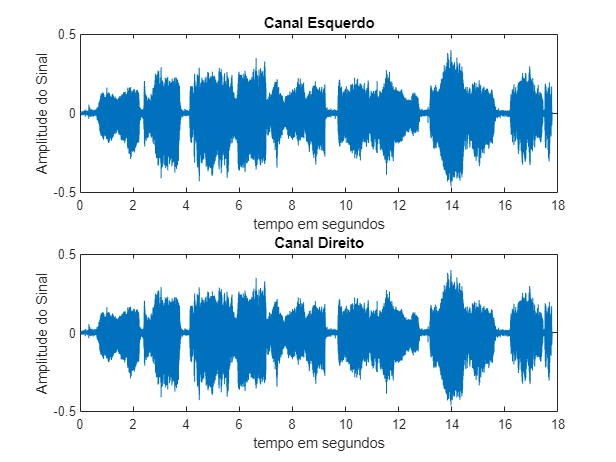


% audioread Read audio files
%   [Y , Fs] = audioread(FILENAME) reads on audio file specified by the
%   character vector or string scalar FILENAME,returning the sampled data
%   in Y and the sample rate FS, in Hertz

[Y , FS] = audioread("Audio_02.wav");

%%Criando a variavel tempo


TS = 1/FS;                                  %tempo entre amostras
Npontos = length(Y);                        %Numero de pontos do veotr Y
Vfinal = (Npontos-1)*TS;                    %Valor final no tempo
tempo = linspace(0,Vfinal,Npontos);         %1/44100 tempo na mesma frequencia do audio

figure(1)
subplot(2,1,1)
plot(tempo,Y(:,1))
xlabel('tempo em segundos')
ylabel('Amplitude do Sinal')
title('Canal Esquerdo')


subplot(2,1,2)
plot(tempo,Y(:,2))
xlabel('tempo em segundos')
ylabel('Amplitude do Sinal')
title('Canal Direito')

## Ouvir um arquivo .wav

%Audiowrite write audio files
%   audiowrite(FILENAME,Y,FS) writes data Y to an audio
%   file specified by the file name FILENAME, with a sample rate of FS Hz
%   Stereo data should be specified as matrix os N columns.

%Sound Play vector as sound.
%   sound(Y,FS) sends the signal in vector 
%
%
%
%
%
%
%
%
%
%



sound(Y,FS);
FY = fftshift(fft(Y));


## Visualizar a FFT e Interpretar 

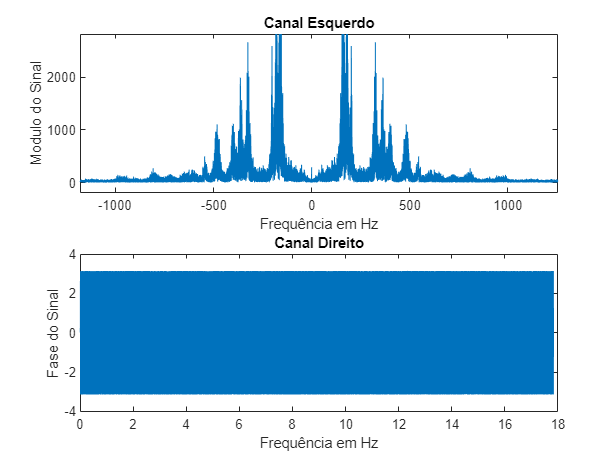

%%Criar a variavel frequencia
frequencia = linspace(-FS/2,FS/2,Npontos);
figure(2)


subplot(2,1,1)
plot(frequencia,abs(FY(:,1)))
xlabel('Frequência em Hz')
ylabel('Modulo do Sinal')
title('Canal Esquerdo')

subplot(2,1,2)
plot(tempo,angle(FY(:,1)))
xlabel('Frequência em Hz')
ylabel('Fase do Sinal') % angulo
title('Canal Direito')

subplot(2,1,1)
xlim([-1179 1254])
ylim([-188 2813])

## Repetição para o arquivo Gaita_Blues - audio 1

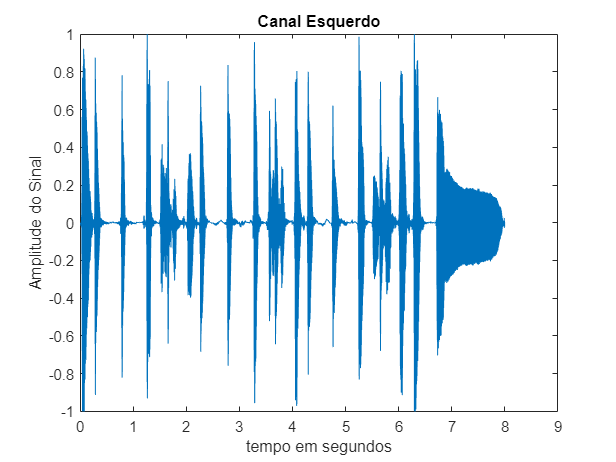


[Y1 , FS1] = audioread("Audio_01.wav");

%%Criando a variavel tempo


TS1 = 1/FS1;                                  %tempo entre amostras
Npontos1 = length(Y1);                        %Numero de pontos do veotr Y
Vfinal1 = (Npontos1-1)*TS1;                    %Valor final no tempo
tempo1 = linspace(0,Vfinal1,Npontos1);         %1/44100 tempo na mesma frequencia do audio

figure(3)
plot(tempo1,Y1(:,1))
xlabel('tempo em segundos')
ylabel('Amplitude do Sinal')
title('Canal Esquerdo')

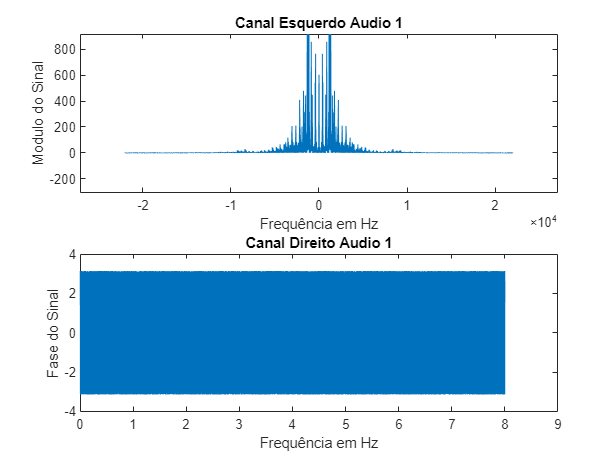





sound(Y1,FS1);
FY1 = fftshift(fft(Y1));




%%Criar a variavel frequencia
frequencia1 = linspace(-FS1/2,FS1/2,Npontos1);
figure(2)


subplot(2,1,1)
plot(frequencia1,abs(FY1(:,1)))
xlabel('Frequência em Hz')
ylabel('Modulo do Sinal')
title('Canal Esquerdo Audio 1')

subplot(2,1,2)
plot(tempo1,angle(FY1(:,1)))
xlabel('Frequência em Hz')
ylabel('Fase do Sinal') % angulo
title('Canal Direito Audio 1')

subplot(2,1,1)
xlim([-27097 27097])
ylim([-306 917])


%fim Aula 1.


### **Inicialização de Vetores**

vetorn = [0:1:9999];
k = vetorn' .* vetorn; %indices de multiplicação da matriz j
%matrizj = [1,2,1,;2,0,0]

%matrizj = [-j,-j,-j,-j;-j,-j,-j,-j;-j,-j,-j,-j;-j,-j,-j,-j;]

g = Y(1:10000)

g =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


n = cos(2*pi/10000)-j*sin(2*pi/10000);


matrizj = n *ones(10000,10000); % matriz j

matrixaux = matrizj.^k; %

x = 1/4*matrixaux*g' % erro

x =    3.7972 + 0.0000i
  -0.3297 + 0.5503i
  -0.1547 - 1.8642i
   3.7129 + 4.0817i
  -0.4576 + 2.0442i
  -3.5041 + 0.6717i
  -0.7038 - 0.9302i
  -0.1486 - 0.3204i
  -0.3865 - 0.2877i
   0.1879 - 1.2392i


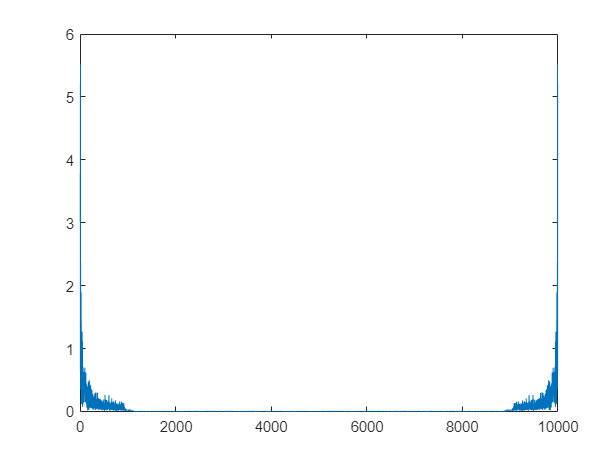


figure(6)
plot(vetorn,abs(x))

%testes
vtp([2:4 7])

vtp([3 7])
b = ones(4,4)


